clear all;
L = 0.127; %m
y_min = -2*L;
y_max = 2*L;

x_min = 0;
x_max = 2*L;

delta = 0.0005;
delta_q = 0.02;
v_x = x_min:delta:x_max;
v_y = y_min:delta:y_max;

v_x_q = x_min:delta_q:x_max;
v_y_q = y_min:delta_q:y_max;


n_x = size(v_x,2);
n_y = size(v_y,2);
n_x_q = size(v_x_q,2);
n_y_q = size(v_y_q,2);


[m_x,m_y] = meshgrid(v_x,v_y);
A1 = zeros(n_y,n_x);
A2 = A1;
P2 = A1; P1 = A1; D = A1; D_v = A1;
O = A1;
ME = A1;

[m_x_q,m_y_q] = meshgrid(v_x_q, v_y_q);
eix1 = zeros(n_y_q,n_x_q);
eiy1 = eix1;
eix2 = eix1;
eiy2 = eix1;
RGA = A1;


for  i = 1:n_x
    for j = 1:n_y
        [A1(j,i),A2(j,i),P1(j,i),P2(j,i),D(j,i),D_v(j,i),O(j,i),RGA(j,i),~,~,~,~,ME(j,i)] = get_q(v_x(i), v_y(j),false);
        
    end
end

for  i = 1:n_x_q
    for j = 1:n_y_q
        [~,~,~,~,~,~,~,~,eix1(j,i),eiy1(j,i),eix2(j,i),eiy2(j,i),~] = get_q(v_x_q(i), v_y_q(j),true);
        
    end
end

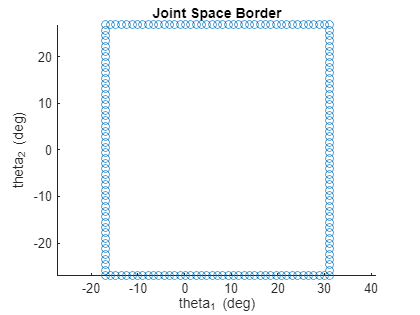

sing = [0,0];
% surf(m_x,m_y,D,"EdgeColor","none");
% title("Rotation Accessibility MAtrix");
% xlabel("x")
% ylabel("y")
% view([-14.88 64.33])
t0_min = deg2rad(-17);
t0_max = deg2rad(31);
t1_min = deg2rad(90-27);
t1_max = deg2rad(90+27);



theta0_v = t0_min:0.02:t0_max;
theta1_v = t1_min:0.02:t1_max;

t0_l = size(theta0_v,2);
t1_l = size(theta1_v,2);

square_angles = [
   theta0_v',    t1_min*ones(1,t0_l)'      ;
   t0_max*ones(1,t1_l)' , theta1_v'  ;
   theta0_v',    t1_max*ones(1,t0_l)'      ;
   t0_min*ones(1,t1_l)' , theta1_v'  ;
   
];
square_angles = square_angles';

square_angles_deg = rad2deg(square_angles);
square_angles_deg(2,:) = square_angles_deg(2,:)-90;
scatter(square_angles_deg(1,:),square_angles_deg(2,:))
title("Joint Space Border")
xlabel("theta_1 (deg)")
ylabel("theta_2 (deg)")
axis equal

%% XY
square_angles_xy = square_angles*0;
for a = 1:size(square_angles,2)
    [square_angles_xy(1,a), square_angles_xy(2,a)] = direct_kinematics(square_angles(1,a),square_angles(2,a)) ;
end




## Figures


center_rect = [0.13 ; 0.135];
rect_s = 0.04;

center_circle = [0.13 ; 0.135]

center_circle =     0.1300
    0.1350


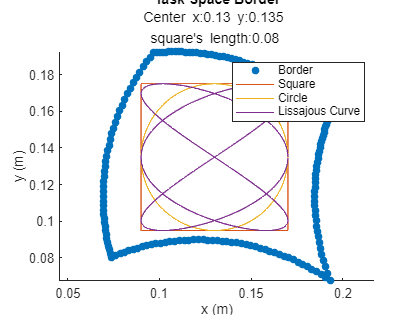

circle_rad = 0.04;
twopi = 0:0.01:2*pi;

x_circ = center_circle(1)+ circle_rad*sin(twopi);
y_circ = center_circle(2)+ circle_rad*cos(twopi);


liss_A = 0.04;
liss_B = 0.04;
x_liss = center_circle(1)+ liss_A*sin(twopi*3+pi/2);
y_liss = center_circle(2)+ liss_B*sin(2*twopi);



scatter(square_angles_xy(1,:),square_angles_xy(2,:),"filled")
hold on
plot([center_rect(1)-rect_s center_rect(1)-rect_s center_rect(1)+rect_s center_rect(1)+rect_s center_rect(1)-rect_s], ...
 [center_rect(2)-rect_s center_rect(2)+rect_s center_rect(2)+rect_s center_rect(2)-rect_s center_rect(2)-rect_s ] )
plot(x_circ,y_circ)
plot(x_liss,y_liss)
% rectangle('Position',[center(1)-rect_s ...
%     center(2)-rect_s ...
%     rect_s*2 rect_s*2])
hold off
% axis([0 10 0 10])
legend("Border","Square","Circle","Lissajous Curve")
title("Task Space Border")
subtitle("Center x:"+center_rect(1)+" y:"+center_rect(2)+" \newline square's length:" +2*rect_s)
xlabel("x (m)")
ylabel("y (m)")
axis equal

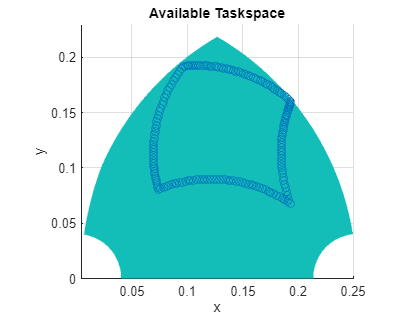


% figure;
% surf(m_x,m_y,D_v,"EdgeColor","none");
% title("Velocity Accessibility MAtrix");
% xlabel("x")
% ylabel("y")
% view([-14.88 64.33])
% 
% 
figure;

surf(m_x,m_y,RGA-1,"EdgeColor","none");
hold on
scatter(square_angles_xy(1,:),square_angles_xy(2,:))
hold off
title("Available Taskspace");
xlabel("x")
ylabel("y")
% view([-14.88 64.33])
axis equal  
view([0 90.00])

xlim([0.004 0.250])
ylim([0 0.23])

% zscale log


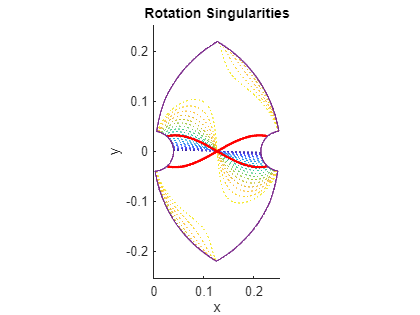


figure
hold on;
contour(m_x,m_y,D,20,"LineWidth",0.01,"LineStyle",":");
contour(m_x,m_y,D,sing,"edgeColor","red","LineWidth",2);
contour(m_x,m_y,O,"edgeColor",[0.4940 0.1840 0.5560]);
title("Rotation Singularities")
xlabel("x")
ylabel("y")
axis equal  
hold off;

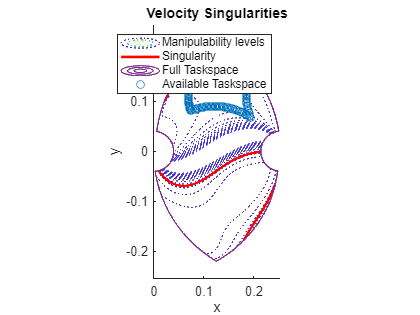




figure
hold on;
contour(m_x,m_y,D_v,20,"LineWidth",0.01,"LineStyle",":");
contour(m_x,m_y,D_v,sing,"edgeColor","red","LineWidth",2);
contour(m_x,m_y,O,"edgeColor",[0.4940 0.1840 0.5560]);
scatter(square_angles_xy(1,:),square_angles_xy(2,:))
legend('Manipulability levels', ...
    'Singularity', ...
    "Full Taskspace", ...
    "Available Taskspace")
title("Velocity Singularities")
xlabel("x")
ylabel("y")
axis equal  
hold off;

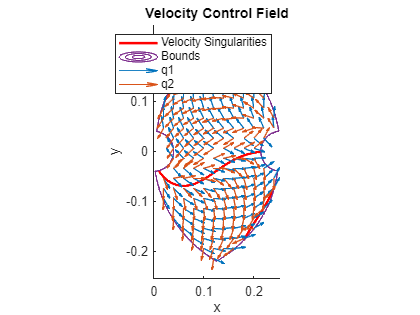



figure
hold on;

% contour(m_x,m_y,ME,20,"LineWidth",0.21,"LineStyle",":");
% contour(m_x,m_y,ME,mesing,"LineWidth",2);
% contour(m_x,m_y,D_v,20,"LineWidth",0.01,"LineStyle",":");
contour(m_x,m_y,D_v,sing,"edgeColor","red","LineWidth",2);
contour(m_x,m_y,O,"edgeColor",[0.4940 0.1840 0.5560]);
title("Velocity Control Field")
xlabel("x")
ylabel("y")
quiver(m_x_q,m_y_q,eix1,eiy1)

quiver(m_x_q,m_y_q,eix2,eiy2)
legend('Velocity Singularities','Bounds',"q1","q2")
axis equal  
hold off;


% contour(m_x,m_y,O,"edgeColor","red");
% title("Bounds");
% xlabel("x")
% ylabel("y")
% view([-0.20 90.00])



% figure
% hold on
% quiver(m_x_q,m_y_q,eix1,eiy1)
% quiver(m_x_q,m_y_q,eix2,eiy2)
% hold off









function [t_a1, t_a2, t_p1, t_p2, d, d_v, inside, rga, eigvecx1, eigvecy1, eigvecx2, eigvecy2, me] = get_q(x,y,quiv)
    
    L = 0.127; %m
    
    [t_a1,t_a2,t_p1,t_p2, error] = inverse_kin(x,y,false);
    if error == 0 
        
        lambda = rot_jacobian(t_a1,t_a2,t_p1,t_p2);
        lambda_v =  vel_jacobian(t_a1,t_a2,t_p1,t_p2);
       
        rga = clamp(rgaf(t_a1,t_a2,false),0.01);    
        if quiv == true
            eigvecx1 = lambda_v(1,1);
            eigvecy1 = lambda_v(2,1);
            eigvecx2 = lambda_v(1,2);
            eigvecy2 = lambda_v(2,2);
            norm1 = sqrt(eigvecx1^2 +eigvecy1^2);
            eigvecx1= lambda_v(1,1)/norm1;
            eigvecy1= lambda_v(2,1)/norm1;
            norm2 = sqrt(eigvecx2^2 +eigvecy2^2);
            eigvecx2= lambda_v(1,2)/norm2;
            eigvecy2= lambda_v(2,2)/norm2;
        else
            
            eigvecx1= -1;
            eigvecy1= -1;
            eigvecx2= -1;
            eigvecy2= -1;
        end
        
        inside = 1;
        d = clamp(det(lambda),1); 
        d_v =  clamp(det(lambda_v),0.1); 
        me =  clamp( det(lambda*lambda') * det(lambda_v*lambda_v'),0.1);  %mixed score
    else
        t_a1 = NaN  ;
        t_a2 = NaN  ;
        t_p1 = NaN  ;
        t_p2 = NaN  ;
        d = NaN  ;
        inside = 0 ;
        d_v = NaN ;
        rga = NaN ;
        eigvecx1= 0;
        eigvecy1= 0;
        eigvecx2= 0;
        eigvecy2= 0;
        me = NaN;
    end
    
end



function c = clamp(value, bound)

    c = max(min(bound,value),-bound);
end
